% 设置工作目录并加载CSV文件
cd 'C:\Users\lsk\Desktop\机器学习'
data = readtable('data.csv');

% 提取特征和标签
features = table2array(data(:, 3:end)); % 特征（从第3列开始到最后一列）
labels = table2array(data(:, 2)); % 标签（第2列）

% 将标签转换为二进制（M:恶性 -> 1, B:良性 -> 0）
binary_labels = strcmp(labels, 'M'); % 逻辑值数组，M为1，B为0

% 划分数据集
cv_partition = cvpartition(binary_labels, 'HoldOut', 0.3);
X_train = features(training(cv_partition), :);
y_train = binary_labels(training(cv_partition));
X_test = features(test(cv_partition), :);
y_test = binary_labels(test(cv_partition));

% 1. 硬间隔SVM训练
linearSVMModel = fitcsvm(X_train, y_train, 'KernelFunction', 'linear', 'BoxConstraint', 1e10);

% 预测与评估
y_pred_linear_svm = predict(linearSVMModel, X_test);
linear_svm_accuracy = sum(y_pred_linear_svm == y_test) / length(y_test);
fprintf('Linear SVM Accuracy: %.2f%%\n', linear_svm_accuracy * 100);

Linear SVM Accuracy: 97.65%



% 2. Logistic回归模型训练
logisticModel = fitglm(X_train, y_train, 'Distribution', 'binomial', 'Link', 'logit');


% 预测与评估
y_prob_logistic = predict(logisticModel, X_test);
y_pred_logistic = y_prob_logistic > 0.5; % 将概率转化为类标签
logistic_accuracy = sum(y_pred_logistic == y_test) / length(y_test);
fprintf('Logistic Regression Accuracy: %.2f%%\n', logistic_accuracy * 100);

Logistic Regression Accuracy: 95.88%



% 3. 改进版SVM模型（MKL）参数优化
kernelFunctions = {'linear', 'rbf', 'polynomial'};
bestAccuracy = 0;
bestMKLModel = [];
for i = 1:length(kernelFunctions)
    for j = i:length(kernelFunctions)
        tempModel = fitcsvm(X_train, y_train, ...
            'KernelFunction', 'polynomial', ...
            'PolynomialOrder', 2, ...
            'BoxConstraint', 1, ...
            'Standardize', true);
        % 交叉验证
        cvModel = crossval(tempModel, 'KFold', 5);
        tempAccuracy = 1 - kfoldLoss(cvModel);
        if tempAccuracy > bestAccuracy
            bestAccuracy = tempAccuracy;
            bestMKLModel = tempModel;
        end
    end
end

% 使用最优模型进行预测和评估
y_pred_best_mkl = predict(bestMKLModel, X_test);
best_mkl_accuracy = sum(y_pred_best_mkl == y_test) / length(y_test);
fprintf('Optimized MKL SVM Accuracy: %.2f%%\n', best_mkl_accuracy * 100);

Optimized MKL SVM Accuracy: 94.71%


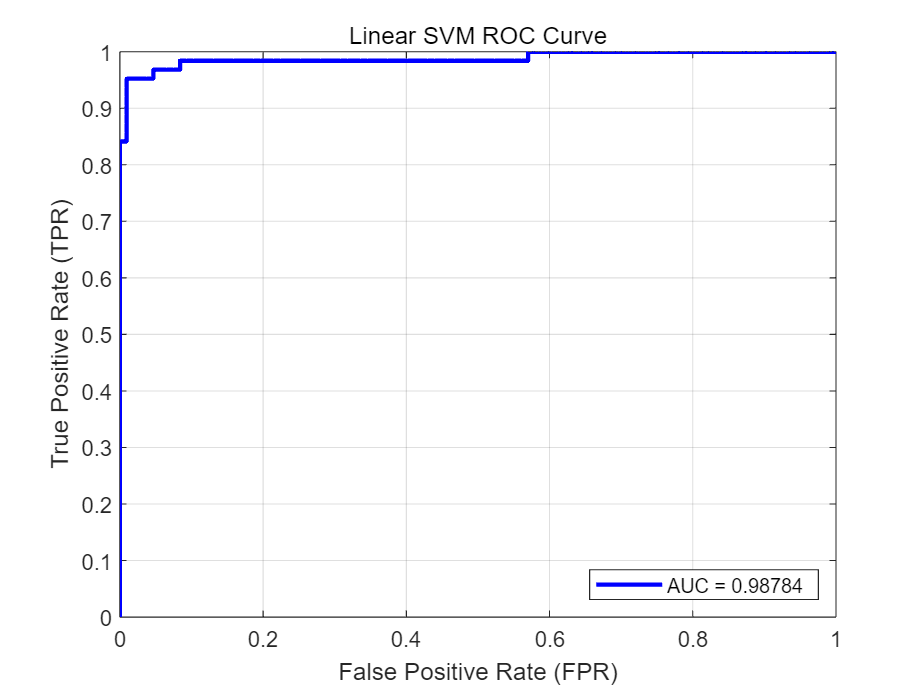



% 4. 计算ROC曲线和AUC
% 计算SVM的ROC曲线和AUC
[~, svm_scores] = predict(linearSVMModel, X_test);
[svm_fpr, svm_tpr, ~, svm_auc] = perfcurve(y_test, svm_scores(:, 2), true);
figure;
plot(svm_fpr, svm_tpr, 'b-', 'LineWidth', 2);
xlabel('False Positive Rate (FPR)');
ylabel('True Positive Rate (TPR)');
title('Linear SVM ROC Curve');
grid on;
legend(['AUC = ', num2str(svm_auc)], 'Location', 'southeast');

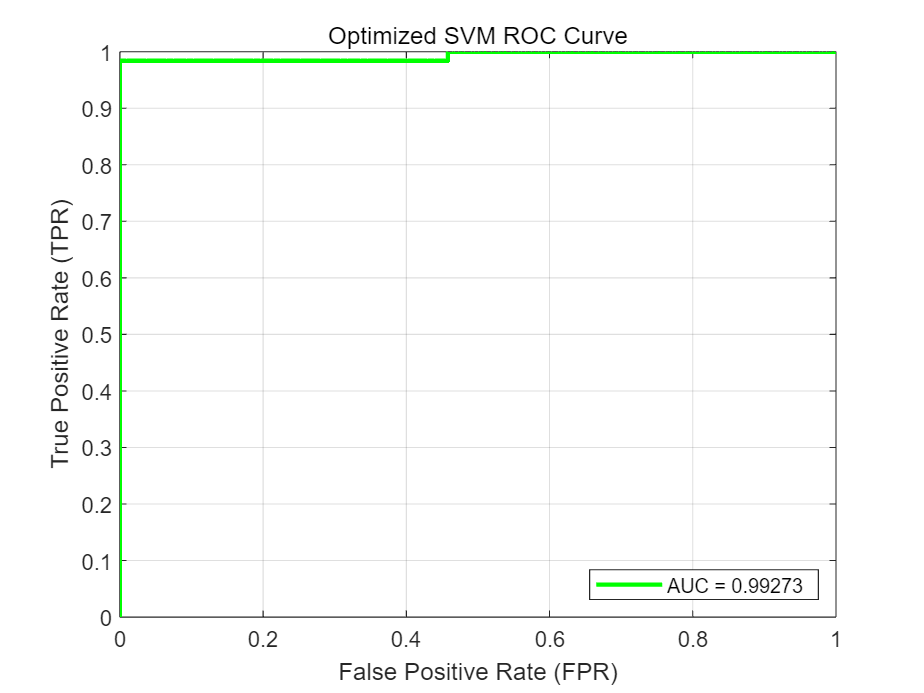


% 计算优化后的SVM的ROC曲线和AUC
[~, best_svm_scores] = predict(bestSVMModel, X_test);
[best_fpr, best_tpr, ~, best_auc] = perfcurve(y_test, best_svm_scores(:, 2), true);
figure;
plot(best_fpr, best_tpr, 'g-', 'LineWidth', 2);
xlabel('False Positive Rate (FPR)');
ylabel('True Positive Rate (TPR)');
title('Optimized SVM ROC Curve');
grid on;
legend(['AUC = ', num2str(best_auc)], 'Location', 'southeast');